# Image Proccessing Project

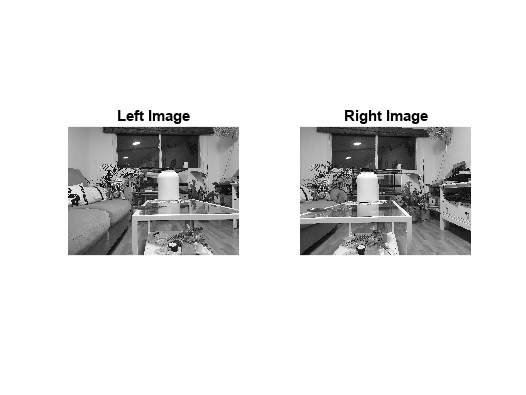

%to do:
%-recognize the wanted object using xcorr- check.
%-getting the dispairity- check.
%getting accurate focal length-check.
%optional-image fix? need to try use 2 photos that have the same height.
%the 1l and 1r have a slight difference in the height.
%making a GUI


clear,clc,clf,close all;

% %cameras
% Cameras.CameraBar = struct();
% Cameras.CameraBen = struct();
% % Set the focal length for Camera1 and Camera2
% Cameras.CameraBar.FocalLength = calibrationSession.CameraParameters.Intrinsics.FocalLength(1);  % Focal length in millimeters
% Cameras.CameraBen.FocalLength = cameraParams.Intrinsics.FocalLength(1);  % Focal length in millimeters
% 
% % Load and assign the images for Camera1
% Cameras.Camera1.Image1 = struct('Image', imread('image1.jpg'), 'T', 0);
% Cameras.Camera1.Image2 = struct('Image', imread('image2.jpg'), 'T', 1);
% Cameras.Camera1.Image3 = struct('Image', imread('image3.jpg'), 'T', 2);
% Cameras.Camera1.Image4 = struct('Image', imread('image4.jpg'), 'T', 3);
% 
% % Load and assign the images for Camera2
% Cameras.Camera2.Image1 = struct('Image', imread('image1.jpg'), 'T', 0);
% Cameras.Camera2.Image2 = struct('Image', imread('image2.jpg'), 'T', 1);
% Cameras.Camera2.Image3 = struct('Image', imread('image3.jpg'), 'T', 2);
% Cameras.Camera2.Image4 = struct('Image', imread('image4.jpg'), 'T', 3);

%load parameters of the cameras:
%load("CameraParamsBen.mat");
load('CamerasData.mat');

% Ben image 1: D=8cm, x1(soda bottle)=84cm, x2(coke bottle)=115cm
% Ben image 2: D=25cm, whey=111.5cm, scissors=72cm, bamba 167cm,
% candle=235cm
%z=?

%read left image
%Il=imread("1l.jpg");
%Il=imread("Ben1L.jpg");
%Il=rgb2gray(Il);
Il=rgb2gray(CamerasData.CameraBen.Image2.LeftImage);
%read right image
% Ir=imread("1r.jpg");
% Ir=imread("Ben1R.jpg");
%Ir=rgb2gray(Ir);
Ir=rgb2gray(CamerasData.CameraBen.Image2.RightImage);

%temp: rotate images because for some reason they are flipped.
 %Il=rot90(rot90(Il));
 %Ir=rot90(rot90(Ir));

%units in cm
%distance between the cameras, I measured.
%D=8; %8cm
T = CamerasData.CameraBen.Image2.T;
%focal length
%f= cameraParams.Intrinsics.FocalLength(1); %getting the focal length in pixels
f = CamerasData.CameraBen.FocalLength;

figure();
subplot(1,2,1);
imshow(Il);
title("Left Image");
subplot(1,2,2);
imshow(Ir);
title("Right Image");

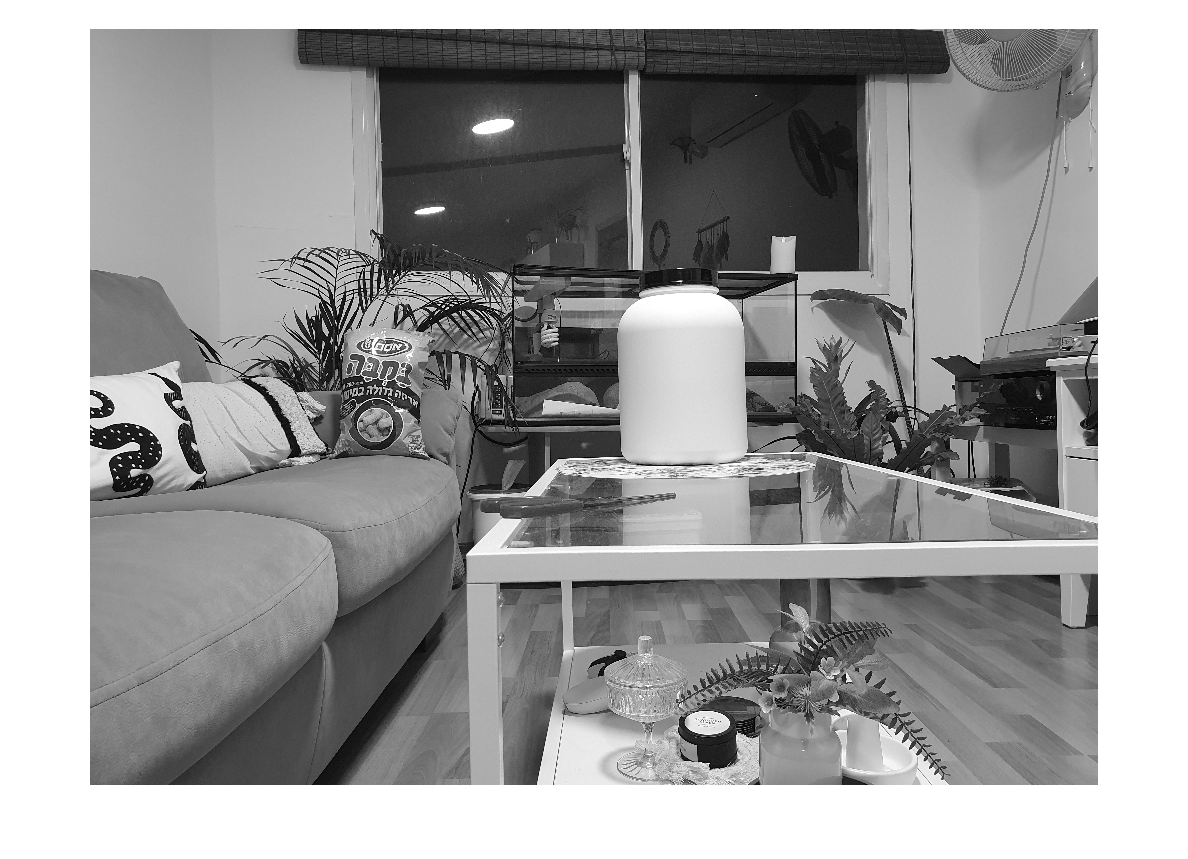


%getting the pixel info of the soda bottle
%(1887, 399)
%(2215, 1447)

% Display the first image
selectObj = figure();
imshow(Il);
title('Select an object by drawing a rectangle');
rect = getrect; % Get the coordinates of the selected rectangle [x, y, width, height]

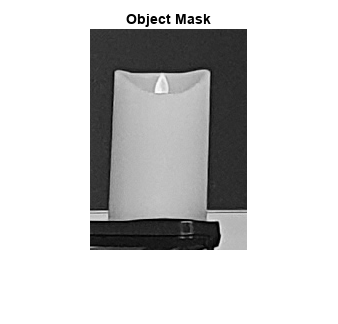


% Extract the object from the first image
object_Mask = imcrop(Il, rect);
close (selectObj);


figure();
imshow(object_Mask);
title("Object Mask");

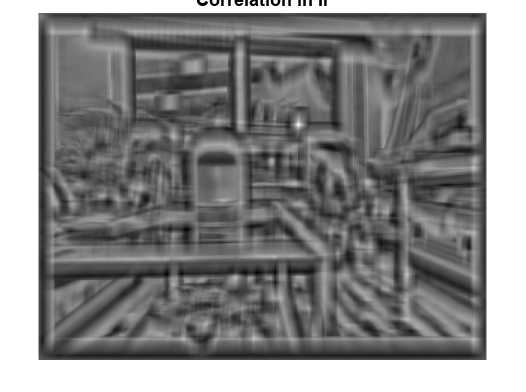


% figure();
% mask_soda=Il([399:1447],[1887:2251]);
% imshow(mask_soda);
% title("Mask Soda");
% 
% %getting the pixel info of the coke bottle
% %(2715, 527)
% %(3031, 1415)
% mask_coke=Il([527:1415],[2715:3031]);
% imshow(mask_coke);
% title("Mask Coke");

%maybe try later to fix an image.
% original_point= [y1 x1; y2 x2];

%getting the correlation
corr_objL = normxcorr2(object_Mask,Il);
corr_objR = normxcorr2(object_Mask,Ir);

% corr_soda1=normxcorr2(mask_soda,Il);
% corr_soda2=normxcorr2(mask_soda,Ir);
% corr_coke1=normxcorr2(mask_coke,Il);
% corr_coke2=normxcorr2(mask_coke,Ir);

%showing the corr result
figure();
% imshow(corr_soda2,[]);
% title("Corr Soda Ir");

imshow(corr_objR,[]);
title("Correlation in Ir");


%getting the original objects corrdinates, temp and might be deleted
 %[original_y1, original_x1] = find(corr_soda1 == max(max(corr_soda1)));
 [original_y1, original_x1] = find(corr_objL == max(max(corr_objL)));
 %[original_y2, original_x2] = find(corr_coke1 == max(max(corr_coke1)));

%getting the shifted objects corrdinates
%[shifted_y1, shifted_x1] = find(corr_soda2 == max(max(corr_soda2)));
[shifted_y1, shifted_x1] = find(corr_objR == max(max(corr_objR)));
%[shifted_y2, shifted_x2] = find(corr_coke2 == max(max(corr2_coke2)));

%creating a shifted point
%shifted_point = [shifted_y1 shifted_x1; shifted_y2 shifted_x2];
% original_point= [original_y1 original_x1; original_y2 original_x2];

% temp- trying to fix an image
% getting the transform using the original point and the shifted point
%  tform = fitgeotform2d(shifted_point,original_point,"similarity");
% 
% sameAsInput = affineOutputView(size(Il),tform,"BoundsStyle","SameAsInput");
% %fixing the image
% imwarp(Il,tform,"OutputView",sameAsInput);


dispairtyX=original_x1-shifted_x1;
dispairtyY=original_y1-shifted_y1;
% H=transltform2d(0,dispairtyY);
% Ir=conv2(Ir,H);
% montage(Il,Ir);
% corr_soda2=normxcorr2(mask_soda,Ir);
% [shifted_y1, shifted_x1] = find(corr_soda2 == max(max(corr_soda2)));
% dispairtyX=original_x1-shifted_x1;
% dispairtyY=original_y1-shifted_y1;

%dispairtyX=x1-shifted_x1;
%dispairtyY=y1-shifted_y1;

%zx=(f*D)/dispairtyX;
Z=(f*T)/dispairtyX;
% Display the calculated distance
%fprintf('The distance of the object is: %.2f centimeters\n', zx);
fprintf('The distance of the object is: %.2f centimeters\n', Z);

The distance of the object is: 181.99 centimeters


%zy=(f*1.59)/dispairtyY;
%result=(zx+zy)/2

## chat

clc,clf,clear;
% Read the two images
image1 = imread('1l.jpg');
image1 = rgb2gray(image1);
image2 = imread('1r.jpg');
image2 = rgb2gray(image2);
% Display the first image
figure;
imshow(image1);
title('Select an object by clicking on it');
object_coords = round(ginput(1)); % Get the coordinates of the selected object

% Get the pixel coordinates of the selected object
object_x = object_coords(1);
object_y = object_coords(2);

% Disparity calculation
window_size = 15; % Size of the matching window
disparity_range = 64; % Range of possible disparities
disparity_map = disparity(image1, image2, 'BlockSize', window_size, 'DisparityRange', [0 disparity_range]);

% Get the disparity value for the selected object
object_disparity = disparity_map(object_y, object_x);

% Calculate the distance (depth) of the object from the camera
D = 8; % Camera displacement (in centimeters)
Z = (2.6 * D) / object_disparity;

% Display the calculated distance
fprintf('The distance of the object is: %.2f centimeters\n', Z);

## chat4-Bar

%Bar's equation: Z=(B*f)/D as Z is distance (meters), B base line (meters),
%d Dispairity (pixel), focal length (pixel).
clear,clc,clf;

% Read the two images
%load("calibrationSession.mat","CameraParameters");
load("calibrationSession.mat");
imageLeft = imread('2l.jpg');
imageLeft = rgb2gray(imageLeft);
imageRight = imread('2r.jpg');
imageRight = rgb2gray(imageRight);
% Display the images
left=figure();
imshow(imageLeft);title("left image");
figure;
imshow(imageRight);title("right image");

%camera specs - iphone 12 pro main camera (in meters)
d = 1.4*10^-6; %pixel size 1.4um
%f = FocalLenght(1); %focal length 26mm
f = calibrationSession.CameraParameters.Intrinsics.FocalLength(1);
T = 0.42; %baseline distance between center of left and right cameras

%find coordinates of object (xl,yl) and the mask with imtool
%imtool(imageLeft);
%imtool(imageRight);
%(2949, 1060)  161
%(3135, 1633)  158
x2=3135;
y2=1633;
[masktest,rect]=imcrop(imageLeft);title("choose mask");
imshow(masktest);title("masktest");
mask = imageLeft([1060:1633],[2949:3135]);
imshow(mask);title("mask");
%%%%%%%   try to do corralation with masktest so we can get the
%%%%%%%   cooradinates automaticly
%normxcorr2 on right image and find coordinates of object (xr,yr)
corr2right=normxcorr2(mask,imageRight);
%imtool(corr2right);title("corr2 image");
x1=round((2949+3135)/2);
y1=round((1060+1633)/2);
[shifted_y1, shifted_x1] = find(corr2right == max(max(corr2right)));
corr2left=normxcorr2(mask,imageLeft);
[shifted_y2, shifted_x2] = find(corr2left == max(max(corr2left)));
%find disparity D = (xl-xr)
D=shifted_x2-shifted_x1;
%calculate distance Z with equation Z=(f/d)*(T/D) 
Z=(T*f/D)*(T/D);
z_distance=(f*T)/D;

## camera struct setup

load("CameraParamsBen.mat");
load("calibrationSession.mat");
%cameras
CamerasData.CameraBar = struct();
CamerasData.CameraBen = struct();
% Set the focal length for CameraBar and CameraBen
CamerasData.CameraBar.FocalLength = calibrationSession.CameraParameters.Intrinsics.FocalLength(1);  % Focal length in millimeters
CamerasData.CameraBen.FocalLength = cameraParams.Intrinsics.FocalLength(1);  % Focal length in millimeters

% Load and assign the images for CameraBar
CamerasData.CameraBar.Image1 = struct('T', 42, 'LeftImage', imread('Bar1L.jpg'), 'RightImage', imread('Bar1R.jpg'));

% Load and assign the images for CameraBen
CamerasData.CameraBen.Image1 = struct('T', 8, 'LeftImage', imread('Ben1L.jpg'), 'RightImage', imread('Ben1R.jpg'));
CamerasData.CameraBen.Image2 = struct('T', 25, 'LeftImage', imread('Ben2L.jpg'), 'RightImage', imread('Ben2R.jpg'));
